# Detector Presets

The Qrackling toolbox allows convenient bundling of detector performance data shipping data for a range of devices covering both avalanche photon diodes and superconducting nanowires, that we have collected either experimentally or extracted from manuals. These can be easily accessed with:

Each of these presets contains data for wavelength dependent detection efficiency, a jitter histogram, the dead time of the detector and a dark count rate. From this we can get an accurate representation of the detector performance at our chosen wavelength, provided its within the range the detector is intended to operate over.

For the preset detector we bundle into the toolbox the following devices are currently available:

- Excelitas

- Hamamatsu

- LaserComponents

- MicroPhotonDevices

- PerkinElmer

- ID_Qube_NIR

- QuantumOpus1550_RoomTemperatureAmplifier

- QuantumOpus1550_CryogenicAmplifier

these names can be used as arguments to components.loadPreset. In the rest of this example we will go through the process of creating a new detector preset that we can use later.

## Loading the Data

For this example the [nanowire detector at 2.1µm from Jin et-al](https://opg.optica.org/prj/fulltext.cfm?uri=prj-10-4-1063&id=470770) will be used. The files used here are available in Examples/Data/ and have been extracted from the paper.

loc = which('components.loadPreset');
[path, ~, ~] = fileparts(loc);
elems = strsplit(path, filesep);
path_root = string(join(elems(1:end-1), filesep)) + filesep;
whichSeparator = @(Path, Sep) Sep{cellfun(@(sep) contains(Path, sep), Sep)};
MakePathNative = @(Path) strjoin(strsplit(Path, whichSeparator(Path, {'/', '\'})), filesep);
example_path = "Examples/Data/detector_data_doi_10_1364_PRJ_437834/";
data_path = path_root + MakePathNative(example_path);

paths = dir(data_path);
FilterStrings = @(haystack, needle) haystack(arrayfun(@(h) contains(h, needle), haystack));
csv_files = FilterStrings({paths.name}, ".csv");
disp(csv_files')

    {'efficiency.csv'   }
    {'pulse_trace.csv'  }
    {'timing_jitter.csv'}



## Detection Efficiency

The paper presents a figure for detection efficiency, we will take some liberties here with the data and interpolate over the four data points. This will give us a reasonable representation of the detector efficiency over its quoted operation range.

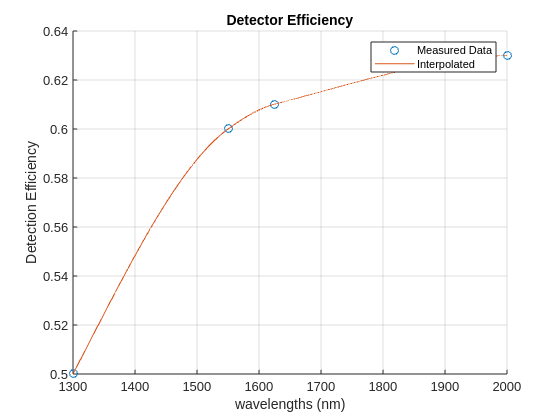

efficiency_data = readtable(data_path + csv_files{contains(csv_files, "efficiency")});

wavelengths = linspace(efficiency_data.Wavelength_nm(1), efficiency_data.Wavelength_nm(end), 1000);
efficiency = interpn( ...
    efficiency_data.Wavelength_nm, ...
    efficiency_data.Efficiency_percent ./ 100, ...
    wavelengths, ...
    'makima');

figure
hold on
grid on
scatter(efficiency_data.Wavelength_nm, efficiency_data.Efficiency_percent ./ 100)
plot(wavelengths, efficiency)
legend("Measured Data", "Interpolated")
xlabel("wavelengths (nm)")
ylabel("Detection Efficiency")
title("Detector Efficiency")
hold off

## Jitter Data

Next we will do the same with the jitter figure presented. For this part of the detector preset we must have equal spacing between each of the data points to use it as a histogram, to achieve this we will again interpolate the data, this time we will do it over a linspace such that we now know that each bin has a width of 1ps.

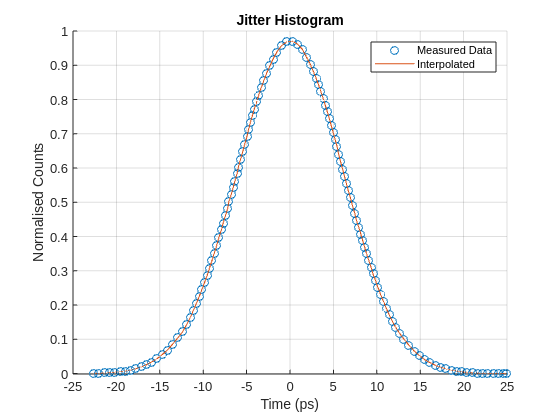

jitter_data = readtable(data_path + csv_files{contains(csv_files, "jitter")});

times = linspace(jitter_data.time_ps(1), jitter_data.time_ps(end), 1000);
counts = abs(interpn(jitter_data.time_ps, jitter_data.normalised_counts, times));

figure
hold on
grid on
scatter(jitter_data.time_ps, jitter_data.normalised_counts)
plot(times, counts)
legend("Measured Data", "Interpolated")
xlabel("Time (ps)")
ylabel("Normalised Counts")
title("Jitter Histogram")
hold off

## Pulse Trace

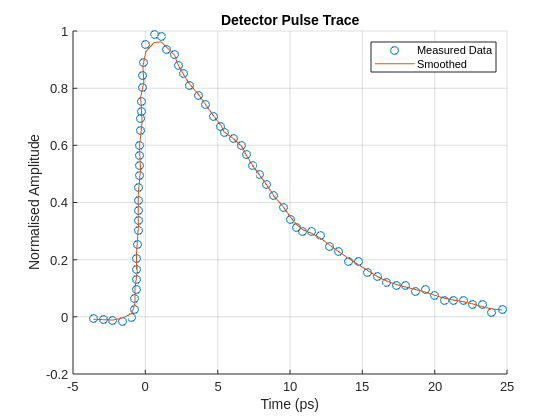

pulse_data = readtable(data_path + csv_files{contains(csv_files, "pulse")});

times_pulse = linspace(pulse_data.Time_ns(1), pulse_data.Time_ns(end), 100);
amplitudes = smoothdata(pulse_data.normalised_amplitude, "gaussian", 6);

figure
hold on
grid on
scatter(pulse_data.Time_ns, pulse_data.normalised_amplitude)
plot(pulse_data.Time_ns, amplitudes)
legend("Measured Data", "Smoothed")
xlabel("Time (ps)")
ylabel("Normalised Amplitude")
title("Detector Pulse Trace")
hold off

## Building the Preset

The class:

provides us a builder interface, we can use the 'add' functions present to build a detector preset and finally call 'makeDetectorPreset()' on this builder to get a validated and complete detector preset object. This is ready to be used with the rest of the toolbox.

superconducting_NbTiN_nanowires_preset = components.DetectorPresetBuilder() ...
    .addName("Single Quantum NbTiN nanowire") ...
    .addDarkCountRate(10) ...
    .addDeadTime(11.6e-9) ... % we know this from the paper
    .addDetectorEfficiencyArray(wavelengths, efficiency) ...
    .addJitterHistogram(counts, 1e-12);
superconducting_NbTiN_nanowires_preset.makeDetectorPreset()

ans =   DetectorPreset with properties:

                   Name: "Single Quantum NbTiN nanowire"
        Dark_Count_Rate: 10
              Dead_Time: 1.1600e-08
       Jitter_Histogram: [6.3744e-04 6.6243e-04 6.8742e-04 7.1241e-04 7.3740e-04 7.6239e-04 7.8738e-04 8.1237e-04 8.3736e-04 8.6235e-04 8.8734e-04 9.1233e-04 9.3732e-04 9.7563e-04 0.0011 0.0011 0.0012 0.0013 0.0014 0.0014 0.0015 0.0016 0.0017 ... ]
    Histogram_Bin_Width: 1.0000e-12
       Wavelength_Range: [1300 1.3007e+03 1.3014e+03 1.3021e+03 1.3028e+03 1.3035e+03 1.3042e+03 1.3049e+03 1.3056e+03 1.3063e+03 1.3070e+03 1.3077e+03 1.3084e+03 1.3091e+03 1.3098e+03 1.3105e+03 1.3112e+03 1.3119e+03 1.3126e+03 1.3133e+03 ... ]
           Efficiencies: [0.5000 0.5003 0.5007 0.5010 0.5014 0.5017 0.5021 0.5024 0.5027 0.5031 0.5034 0.5038 0.5041 0.5045 0.5048 0.5051 0.5055 0.5058 0.5062 0.5065 0.5069 0.5072 0.5075 0.5079 0.5082 0.5086 0.5089 0.5093 0.5

Alternatively, we might want to use this data later and save ourselves the building process. The 'writePreset' function will validate the data held in the builder class and save it to the specified file path.

save_path = strjoin([string(userpath), "superconducting_NbTiN.mat"], filesep);
superconducting_NbTiN_nanowires_preset.writePreset(save_path);

We can then use the preset we created like so:

my_preset = components.DetectorPresetBuilder().loadPreset(save_path)

my_preset =   DetectorPreset with properties:

                   Name: "Single Quantum NbTiN nanowire"
        Dark_Count_Rate: 10
              Dead_Time: 1.1600e-08
       Jitter_Histogram: [6.3744e-04 6.6243e-04 6.8742e-04 7.1241e-04 7.3740e-04 7.6239e-04 7.8738e-04 8.1237e-04 8.3736e-04 8.6235e-04 8.8734e-04 9.1233e-04 9.3732e-04 9.7563e-04 0.0011 0.0011 0.0012 0.0013 0.0014 0.0014 0.0015 0.0016 0.0017 ... ]
    Histogram_Bin_Width: 1.0000e-12
       Wavelength_Range: [1300 1.3007e+03 1.3014e+03 1.3021e+03 1.3028e+03 1.3035e+03 1.3042e+03 1.3049e+03 1.3056e+03 1.3063e+03 1.3070e+03 1.3077e+03 1.3084e+03 1.3091e+03 1.3098e+03 1.3105e+03 1.3112e+03 1.3119e+03 1.3126e+03 1.3133e+03 ... ]
           Efficiencies: [0.5000 0.5003 0.5007 0.5010 0.5014 0.5017 0.5021 0.5024 0.5027 0.5031 0.5034 0.5038 0.5041 0.5045 0.5048 0.5051 0.5055 0.5058 0.5062 0.5065 0.5069 0.5072 0.5075 0.5079 0.5082 0.5086 0.5089 0.50